# REDES NEURONALES PARA CLASIFICACIÓN

En este ejemplo de utilización de redes neuronales para clasificación se trabajará con el conjunto de datos de flores Iris de Ronald Fisher.

Fisher midió cuatro características de 50 ejemplares de tres especies Iris, largo y ancho de los sépalos y largo y ancho de los pétalos. Con este conjunto de medídas, en centímetros, Fisher desarrolló un modelo de clasificador lineal para distinguir entre las tres especies: setosa, versicolor y virginica.

# 1) Carga de los datos de flores Iris obtenidos por Ronald Fisher

Primero se cargan los datos en el espacio de trabajo de Matlab, ejecutando la siguiente instrucción en la ventana de comandos. Tras ejecutarla, aparecen las variables 'caracteristicas'  y 'clasificacion' en el espacio de trabajo. ¿Qué información contienen esas dos variables?

carga_datos_visualizacion

# 2) Visualización de los datos: ¿De qué manera podemos clasificar visualmente los datos en base a las características?

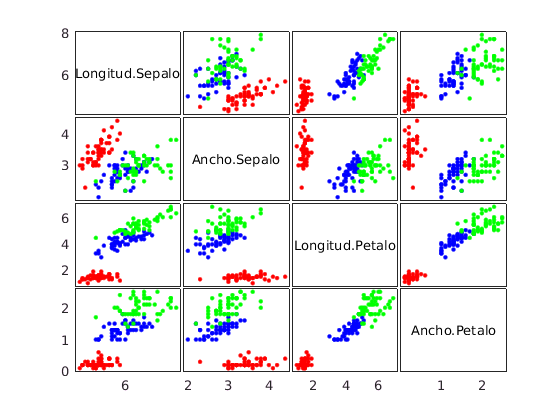

figure(1)
gplotmatrix(caracteristicas, [], clasificacion, ['r', 'b', 'g'],[],[],'off','variable',{'Longitud.Sepalo','Ancho.Sepalo','Longitud.Petalo','Ancho.Petalo'}); % Hacemos un plot enfrentando a todas las características

%[media,std] = grpstats(caracteristicas,clasificacion,{'mean','std'})

¿Qué dos características eligirías para distinguir entre especies de Iris? ¿Cuál sería la peor elección?

# 3) Creación y entrenamiento de la red neuronal para clasificación de flores Iris

## 3.1) Definición de la red

red = define_red;
view(red);

Describe la red, ¿cuántas capas ocultas tiene? ¿cuántas neuronas cada capa?

## 3.2) Entrenamiento de la red

carga_datos_entrenamiento;
[red_entrenada,info_entrenamiento] = entrena_red(red,caracteristicas,clasificacion);

## 3.3) ¿Cuál es la precisión de la red al clasificar?

clasificacion_red=red_entrenada(caracteristicas);
performance = perform(red_entrenada,clasificacion,clasificacion_red);
precision=evalua_red(clasificacion,clasificacion_red);

accuracy = 98

¿Cuá es el significado de este valor de precisión?

## 3.4) Visualización de la función de pérdida

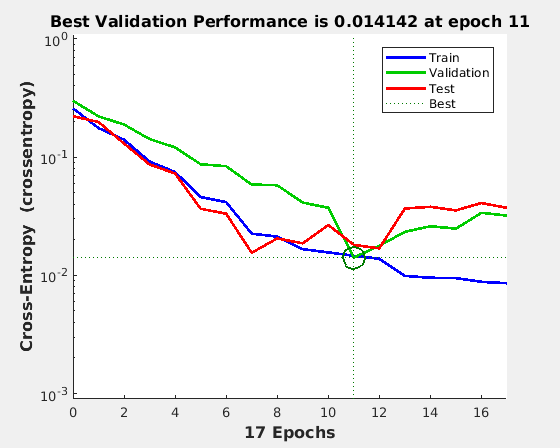

figure, plotperform(info_entrenamiento)

¿Qué ocurre cuando el entrenamiento alcanza el óptimo de validación?

# 4) Utiliza la red para clasificar una flor Iris en base a sus características

## 4.1) Con un ejemplar nuevo, clasificar a qué especie pertenece utilizando la red entrenada.

Con un ejemplar desconocido para la red (no utilizado durante su entrenamiento), ¿a qué clase pertenece realmente?

[flor,clasificacion_flor]=obtener_ejemplar

Index exceeds matrix dimensions.

Error in obtener_ejemplar (line 6)
floresNuevas_especie=clasificacion(:,info_entrenamiento.testInd);

red_entrenada(flor)

## 4.2) La red no acierta en todos los casos

[mal_clasificadas_caracteristicas,mal_clasificadas_clasificacion_red,mal_clasificadas_clasificacion_real]=obtener_mal_clasificadas

Index exceeds matrix dimensions.

Error in obtener_mal_clasificadas (line 20)
clasificacion_test=clasificacion(:,info_entrenamiento.testInd); 

¿Se ha equivocado la red? ¿Dónde?

red_entrenada(mal_clasificadas_caracteristicas)

# 4) Observa cómo se ha definido la red

type define_red.m